# ADXL


filename = "output_adxl_data.csv"

filename = "output_adxl_data.csv"

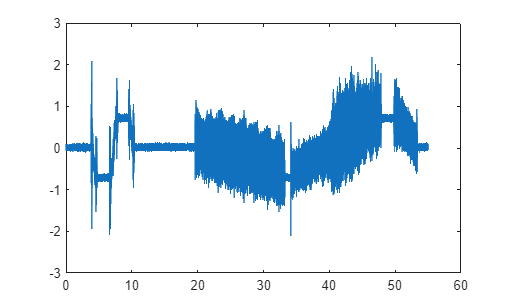


data = readmatrix(filename);

t = data(:,1);
x = data(:,2);
y = data(:,3);
z = data(:,4);

module = sqrt(x.^2 + y.^2 + z.^2);

figure;
plot(t, x);


Fs = 1/(t(2)-t(1)); % sampling frequency

%% ===== COMPUTE CWT =====
% 'amor' = Morlet wavelet (nejlepší pro vibrace)
[cfs, F] = cwt(x, Fs, 'amor');

% převod na dB
C_dB = 20*log10(abs(cfs) + 1e-12);

set(0,'DefaultFigureVisible','on')

%% ===== PLOT =====
figure;
imagesc(t, F, C_dB);
axis xy;

set(gca, 'YScale', 'log');   % log frekvence

xlabel('Čas [s]');
ylabel('Frekvence [Hz]');

colormap(jet);
cb = colorbar;
cb.Label.String = 'Amplituda [dB re 1g]';

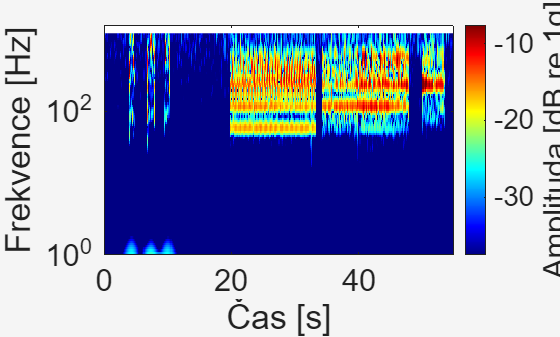

cb.Label.FontSize = 23;

% dynamický rozsah
clim([max(C_dB(:))-40, max(C_dB(:))-10]);

% omezení frekvenčního rozsahu (upravit dle potřeby)
ylim([1 1600]);

set(gca, 'FontSize', 23);

## ADC


filename = "output_adc0_data.csv"

filename = "output_adc0_data.csv"

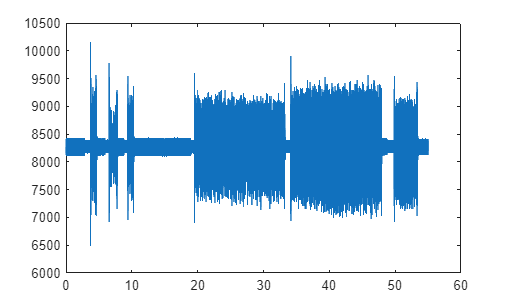


data = readmatrix(filename);

t = data(:,1);
ch1 = data(:,2);
ch2 = data(:,3);

module = ch1;

figure;
plot(t, module);


Fs = 1/(t(2)-t(1)); % sampling frequency

%% ===== COMPUTE CWT =====
% 'amor' = Morlet wavelet (nejlepší pro vibrace)
[cfs, F] = cwt(x, Fs, 'amor');

% převod na dB
C_dB = 20*log10(abs(cfs) + 1e-12);

set(0,'DefaultFigureVisible','on')

%% ===== PLOT =====
figure;
imagesc(t, F, C_dB);
axis xy;

set(gca, 'YScale', 'log');   % log frekvence

xlabel('Čas [s]');
ylabel('Frekvence [Hz]');

colormap(jet);
cb = colorbar;
cb.Label.String = 'Amplituda [dB re 1g]';

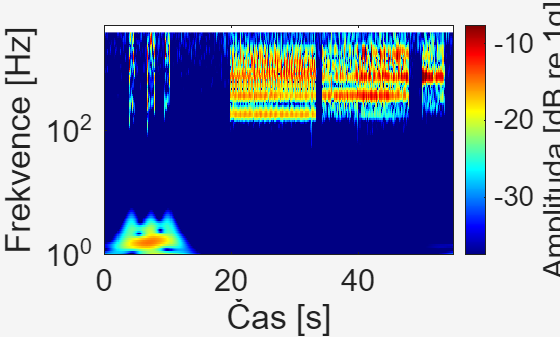

cb.Label.FontSize = 23;

% dynamický rozsah
clim([max(C_dB(:))-40, max(C_dB(:))-10]);

% omezení frekvenčního rozsahu (upravit dle potřeby)
ylim([1 5000]);

set(gca, 'FontSize', 23);